Teste en linear

D = 0.2

D = 0.2000

x0=0;
y0=0;

ksi1 = 1;
wn1 = 5/2;

ksi2 = 1;
wn2 = 5/0.25;

ksi3 = 1;
wn3 = 5/2;

ki1=2*wn1^2;
kp1 = 2*(ksi1/wn1)*ki1;

ki2=D*wn2^2;
kp2 = 2*(ksi2/wn2)*ki2;

ki3=1*wn3^2;
kp3 = 2*(ksi3/wn3)*ki3;



(NL)

L = 0.2;
R = 0.1;


vref = 0.1;
wref=0;


g=25;
ksi=1; 

Pathx = [0 1 8 8 1]

Pathx =      0     1     8     8     1


Pathy = [0 1 1 8 8]

Pathy =      0     1     1     8     8


Paththeta = [0.78 0.78 0 1.57 3.14]

Paththeta =     0.7800    0.7800         0    1.5700    3.1400


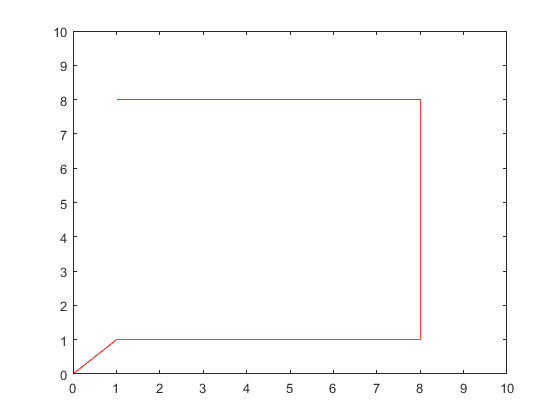



% X_ref1 = out.x1.Data;
% Y_ref1 = out.y1.Data;
% t1 = out.y1.Time;
% 
% X_ref2 = out.x2.Data;
% Y_ref2 = out.y2.Data;
% t2 = out.y2.Time;
% 
% 
 plot(Pathx,Pathy,'r')
 xlim([0 10])
 ylim([0 10])

(Motor Control)

load TF_Motor.mat x
load TF_Motor.mat y
K = 0.1

K = 0.1000

Out = 0.63*K

Out = 0.0630

tau = 0.03 - 0.0205

tau = 0.0095

Te=5/1000;
    
sys = tf([10*K],[tau 1],'InputDelay',0.0205)

sys =
 
                        1
  exp(-0.0205*s) * ------------
                   0.0095 s + 1
 
Continuous-time transfer function.



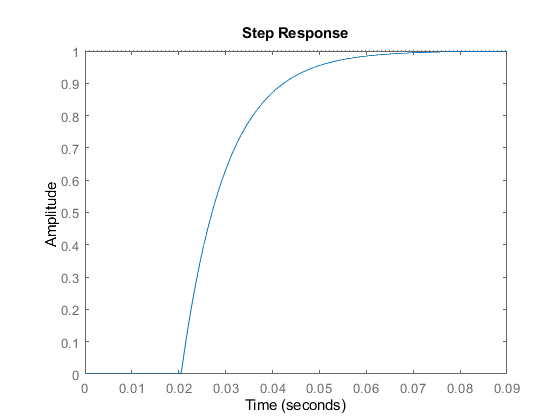

%sys = tf([K],[tau 1])
step(sys);


% pidTuner(sys,'PID')
% 
mypi = pidtune(sys,'pi')

mypi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.279, Ki = 26.6
 
Continuous-time PI controller in parallel form.



% step(feedback(mypi*sys,1))

sys_d=c2d(sys,Te,'zoh')

sys_d =
 
           0.3773 z + 0.03193
  z^(-5) * ------------------
               z - 0.5908
 
Sample time: 0.005 seconds
Discrete-time transfer function.



%sys_d_bf=feedback(sys_d*K,1,-1)

C0 = pid(0.279,26.6,'Ts',Te,'IFormula','BackwardEuler');  
C = pidtune(sys_d,C0)

C =
 
             Ts*z 
  Kp + Ki * ------
              z-1 

  with Kp = -0.0025, Ki = 1, Ts = 0.005
 
Sample time: 0.005 seconds
Discrete-time PI controller in parallel form.

